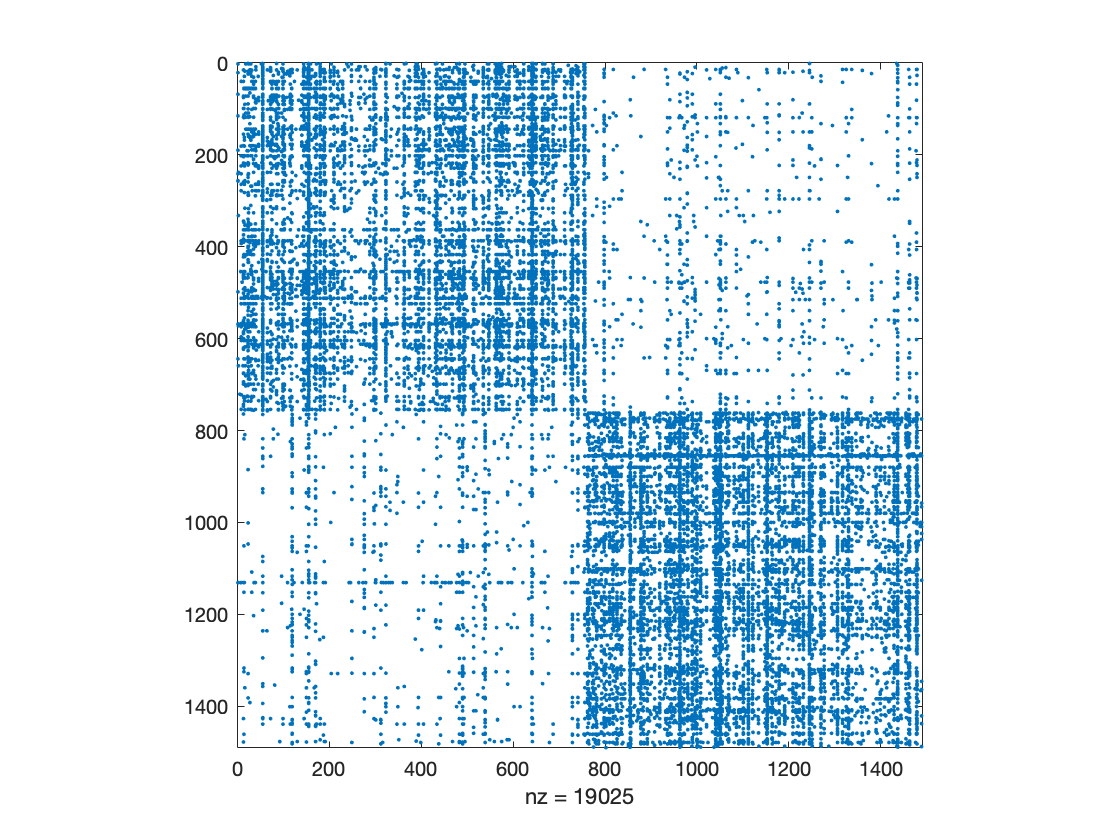

clear
%load("spectralGraphPartitioning-karate.mat");
load("spectraGraphPartitioning-polblogs.mat");
% load("spectralGraphPartitioning_circle_3.mat");
% load("spectralGraphPartitioning_circle_4.mat");

A = Problem.A;
spy(A);

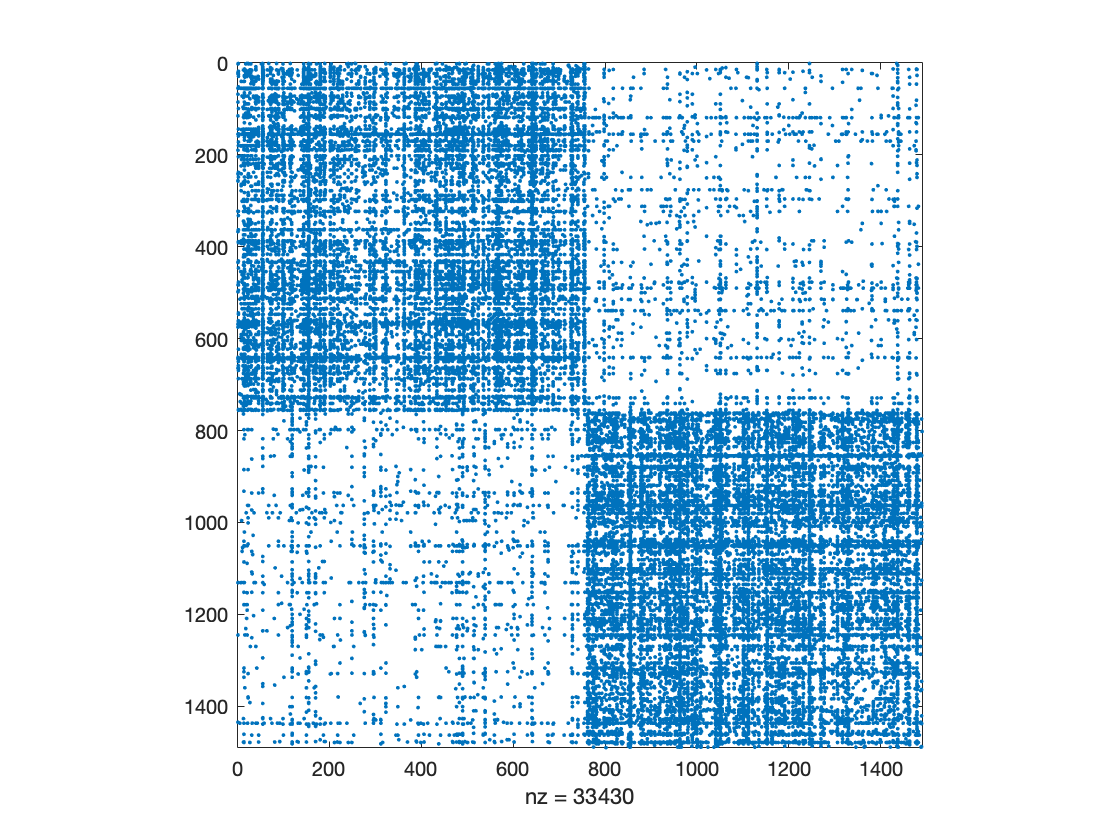


A=A+A';
A=A-diag(diag(full(A)));
spy(A)

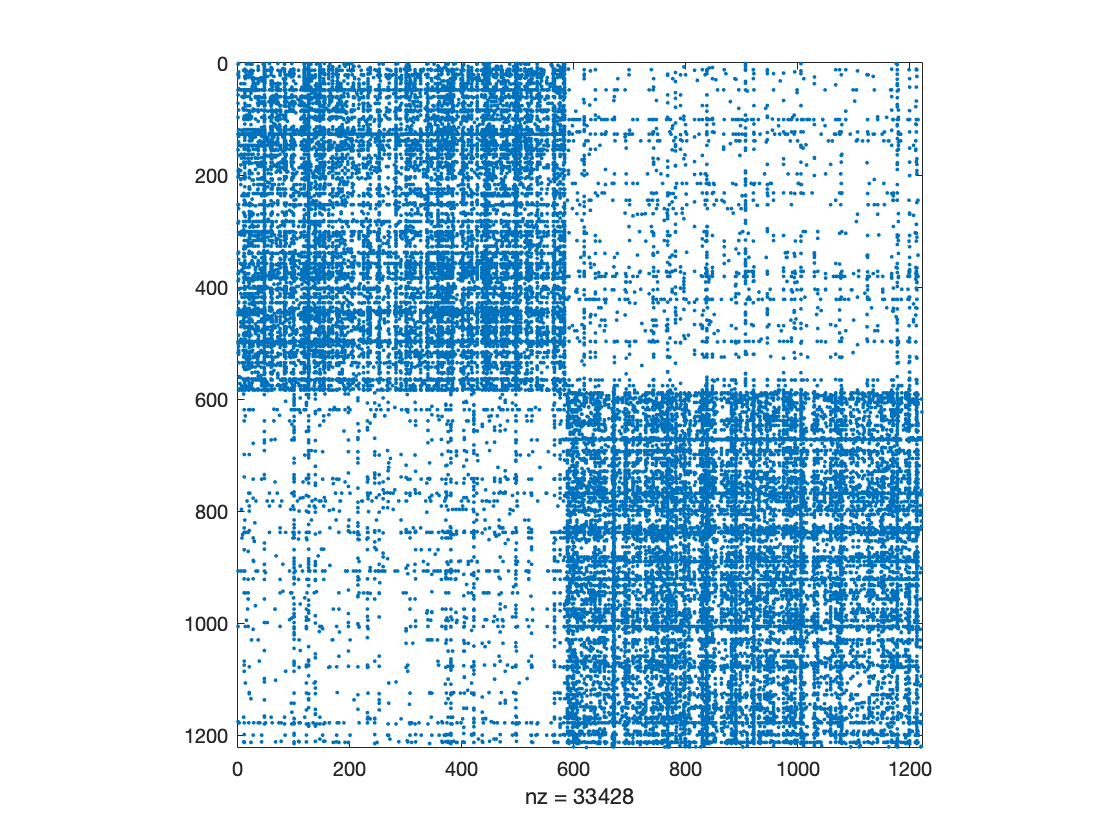

G=graph(A);
bins=conncomp(G);
ind=find(bins==1);
Af=A(ind,ind);

spy(Af)

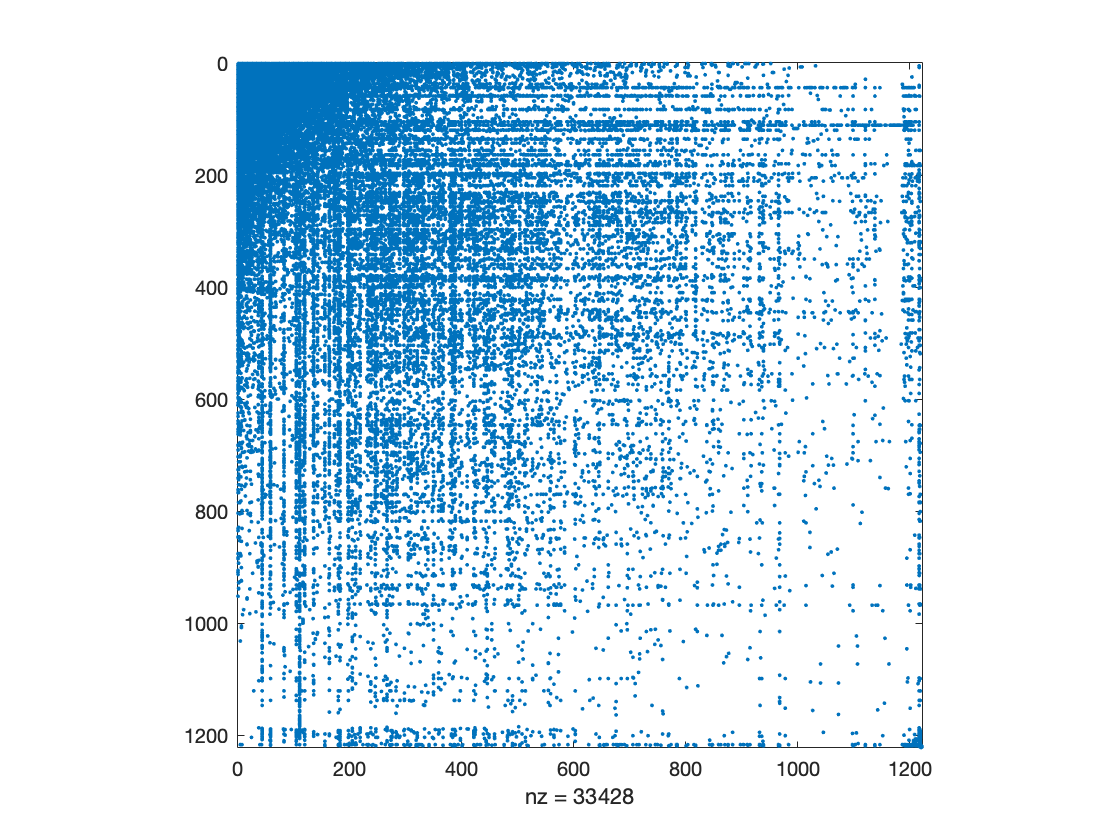


[Ap,P,p, Fiedler,d]=sgp(Af);

spy(Ap);

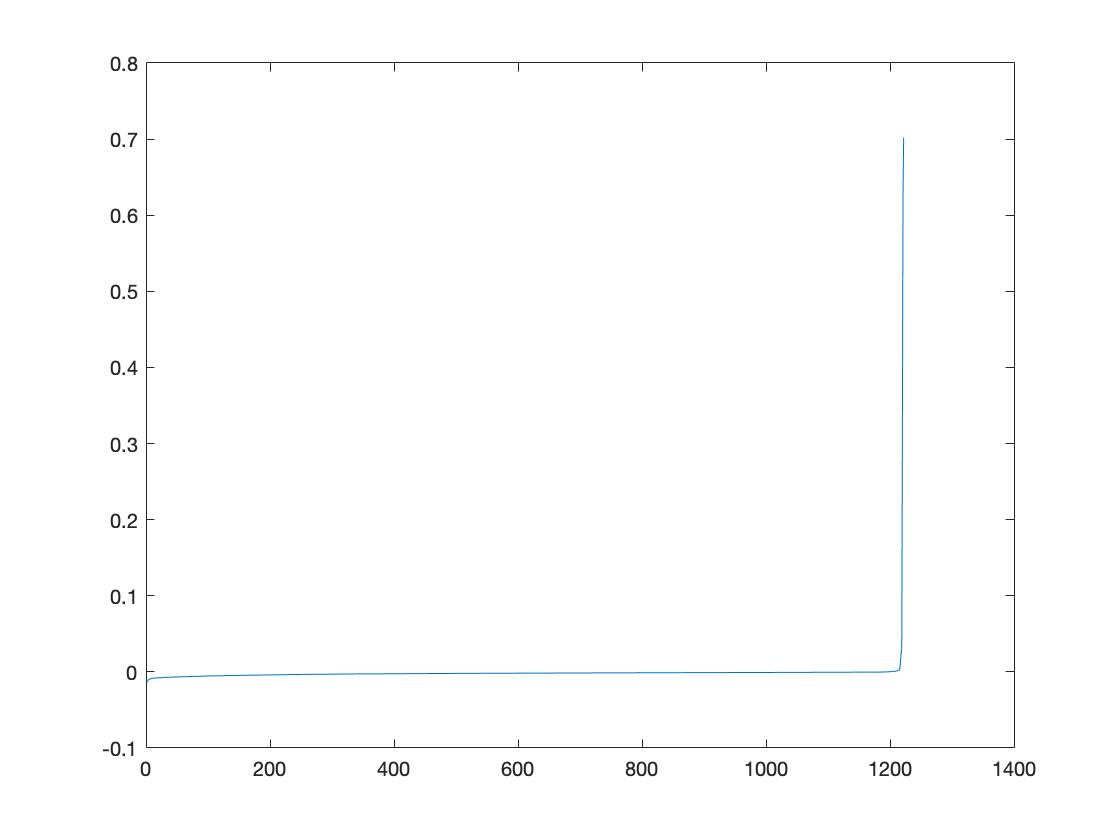


plot(Fiedler(p),'-');

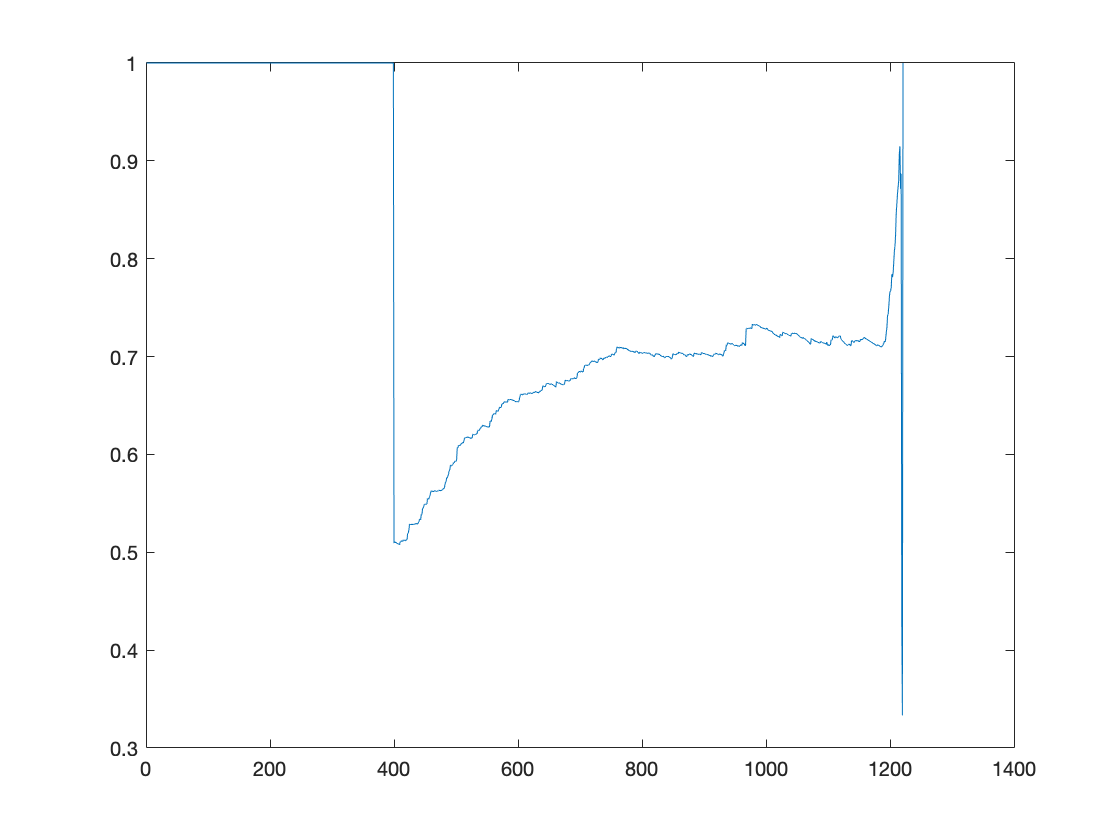


dp = P*d;

cond = ones(length(dp),1);

for m=400:length(dp)
%      % We save each cond value with the ind
%      % of that value in the second col.
     cond(m,1) = sum(Ap(1:m,m+1:end),"all") /...
      min(sum(dp(1:m)),sum(dp(m+1:end)));

end

plot(cond(:,1),'-');

[~,minInd] = min(cond(:,1))

minInd = 1220

n=minInd

n = 1220

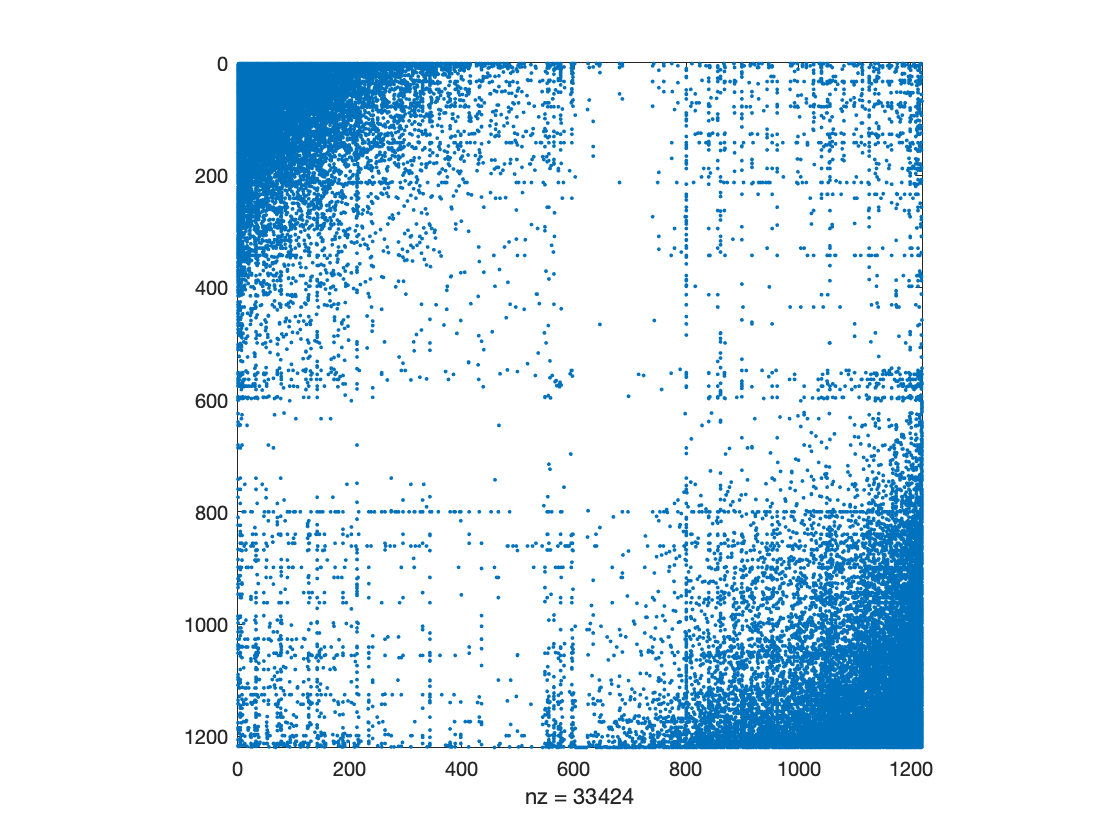


Ap2=Ap(1:n,1:n);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[Ap1,P1,p1, Fiedler1,d1]=sgp(Ap2);

spy(Ap1);

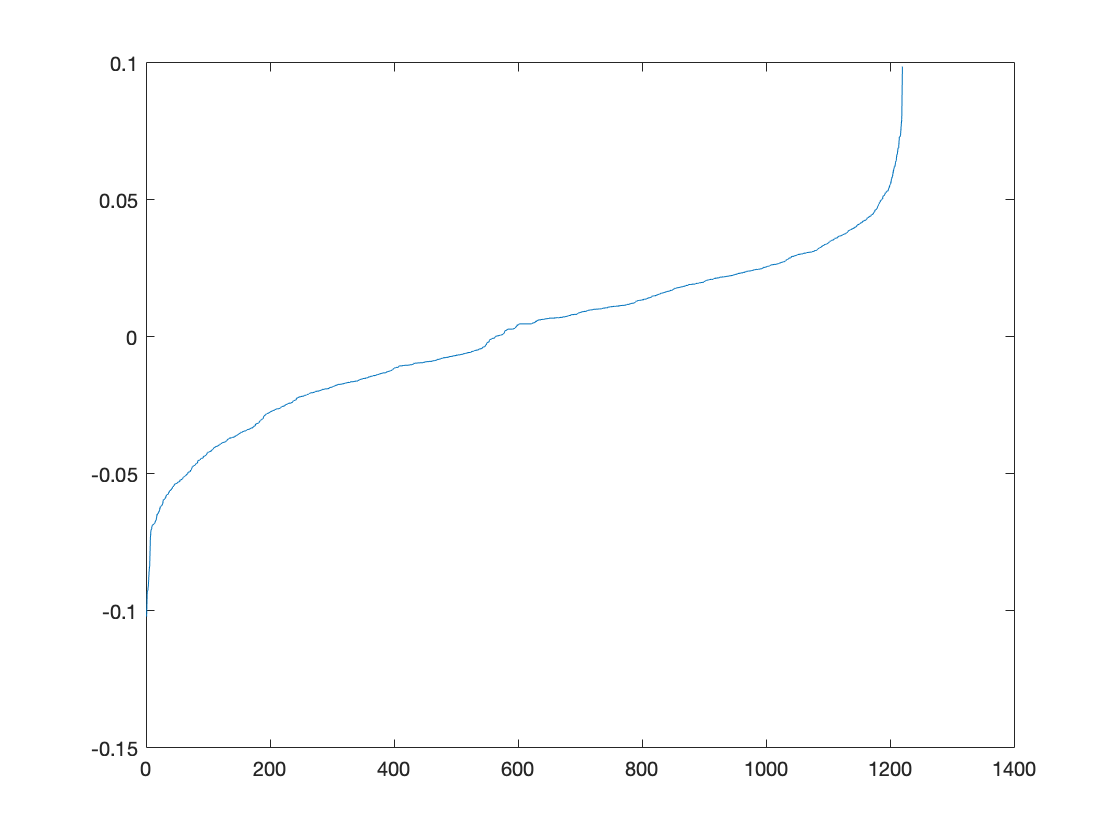


plot(Fiedler1(p1),'-');

[~,n1] = min(abs(Fiedler1(p1)))

n1 = 563

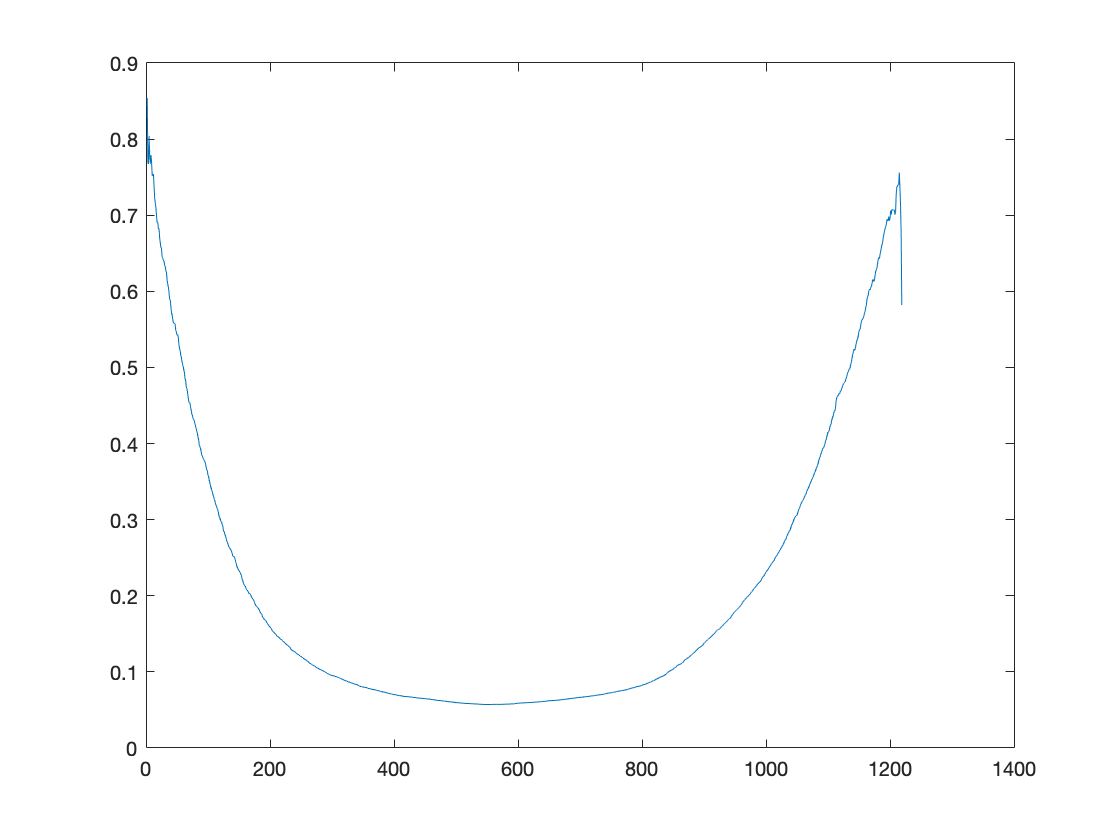

dp1 = P1*d1;

cond1 = ones(length(dp1),1);

for m=1:length(dp1)
%      % We save each cond value with the ind
%      % of that value in the second col.
     cond1(m,1) = sum(Ap1(1:m,m+1:end),"all") /...
      min(sum(dp1(1:m)),sum(dp1(m+1:end)));

end

plot(cond1(:,1),'-');

[~,minInd] = min(cond1(:,1))

minInd = 551

n=minInd

n = 551